clc
clear all

% Define symbolic variables
syms L1 L2 theta1 theta2

% x and y co-ordinates of the end effector
x = L2*cos(theta1+theta2) + L1*cos(theta1)

$$x = L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)$$

y = L2*sin(theta1+theta2) + L1*sin(theta1)

$$y = L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)$$


% Substituting the lengths of the links
fx(theta1,theta2) = subs(x,[L1 L2],[4 2])

$$fx(theta1, theta2) = 2\,\cos\left(\theta_{1}+\theta_{2}\right)+4\,\cos\left(\theta_{1}\right)$$

fy(theta1,theta2) = subs(y,[L1 L2],[4 2])

$$fy(theta1, theta2) = 2\,\sin\left(\theta_{1}+\theta_{2}\right)+4\,\sin\left(\theta_{1}\right)$$

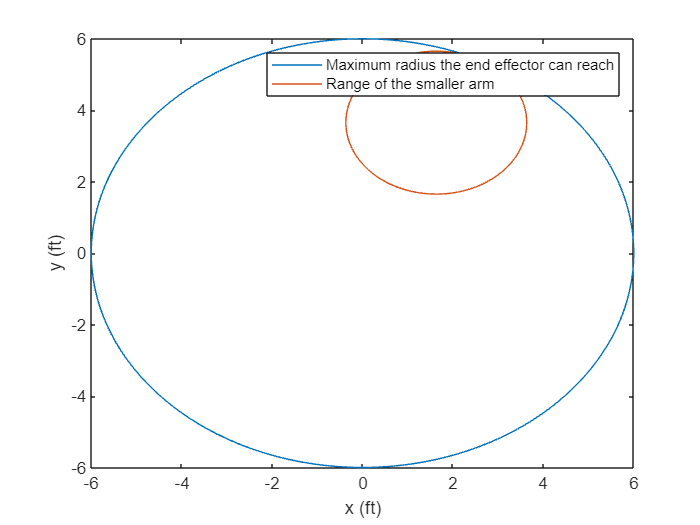


% Position of end effector when arm is 
% fully extended
figure()
fplot(fx(theta1,0),fy(theta1,0))
hold on

% Position of end effector when only
% L2 moves
fplot(fx(20,theta2),fy(20,theta2))
legend('Maximum radius the end effector can reach','Range of the smaller arm')
xlabel('x (ft)')
ylabel('y (ft)')
hold off

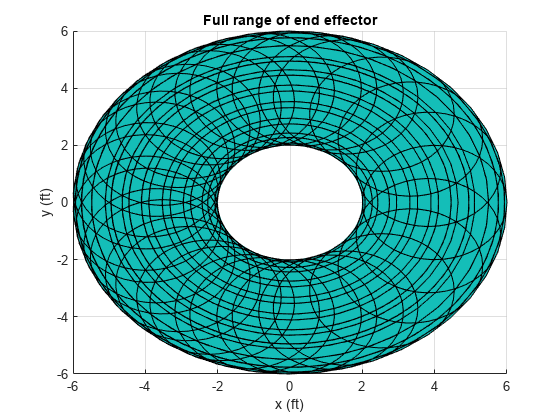


% Position of end effector
figure()
fsurf(fx,fy,0)
view(2)
title('Full range of end effector')
xlabel('x (ft)')
ylabel('y (ft)')